# Simulación con Simulink para el modelo presa-depredador

## Presa - Depredador

Tomaremos el modelo presa depredador:


$$\dot{P}(t)= \alpha P(t) - \beta P(t)D(t)\\
\dot{D}(t)= \delta P(t) D(t) - \gamma D(t)$$


**Con los siguientes parámetros y estados:**

$P(t)$: Número de presas en el tiempo

$D(t)$: Depredadores en el tiempo

$\alpha$: Tasa instantánea de aumento de presas en ausencia de depredadores

$\beta$: Tasa de cacería de número de presas por depredador

$\delta$: Tasa de aumento de depredadores por presa cazada

$\gamma$: Tasa instantánea de disminución de depredadores en ausencia de presas

Tenga en cuenta que para realizar la simulación de un modelo matemático utilizando Simulink se debe crear el modelo como un diagrama de bloques. A continuación se presentarán dos formas de crear los diagramas de bloque:

**Archivo PresaDepredador_ejm1:  **un diagrama de bloques clásico con sus respectivos bloques de funciones, parámetros y entrada.

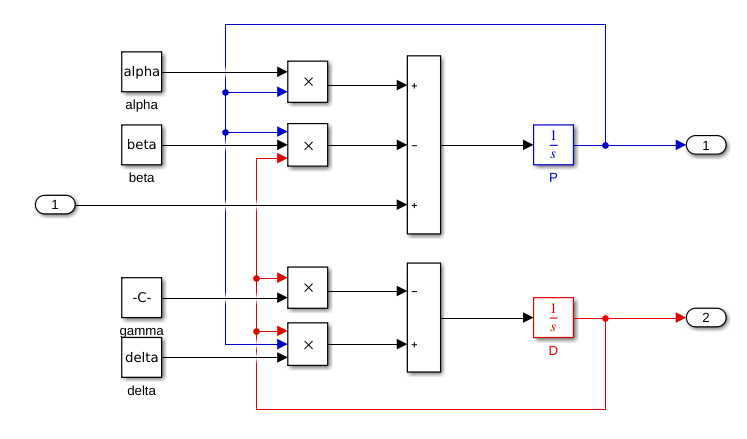

**Archivo PresaDepredador_ejm2: **un par de bloques llamados *Fcn* que representan cada ecuación y resumen los bloques funcionales y de parámetros

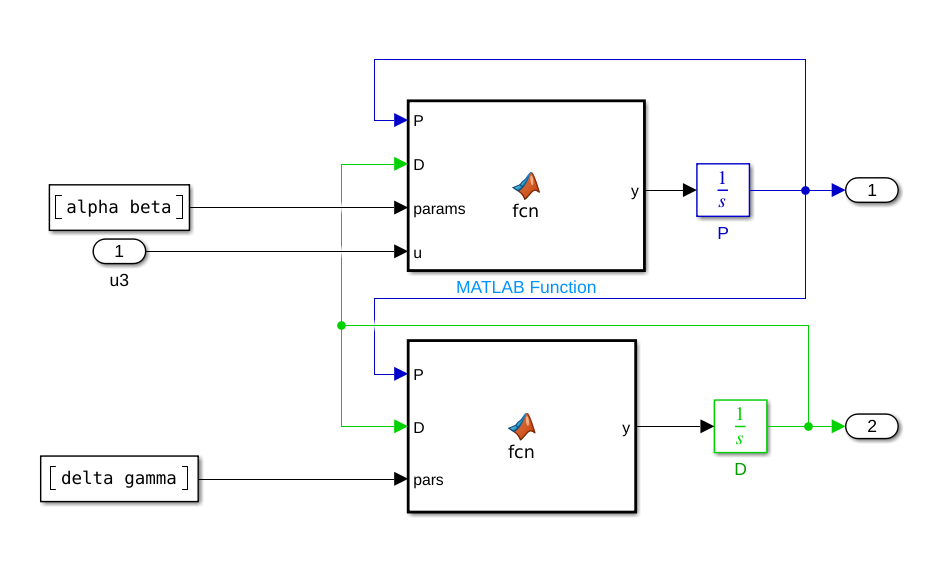

Las funciones dentro de cada bloque son:

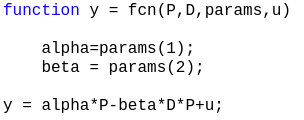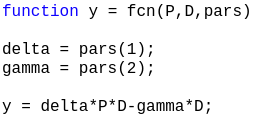

**Nota 1: **En ambos casos, la entrada corresponde a la suma de presas en cada instante de tiempo.

**1.** Definición de los componentes del modelo: Condiciones iniciales, parámetros, valor de las entradas 

**Nota 2:** la entrada *u *es constante, es decir, entra la misma cantidad de presas en cada instante de tiempo.

addpath("Modelos")
%condiciones iniciales
P0 = 3;
D0 = 3;

%Parametros
alpha = 1;
beta = 1;
delta = 1;
gamma = 1;

%entrada
u = 1;

%Tiempo de simulacion
Time = 50;

**2. **Realizar el proceso de simulación del modelo se simulink llamado *PresaDepredador_ejm2.slx *con una entrada constante

options = simset('SrcWorkspace', 'current');
sim('PresaDepredador_ejm2.slx', [], options);

**3. **Graficar los resultados obtenidos de la anterior simulación 

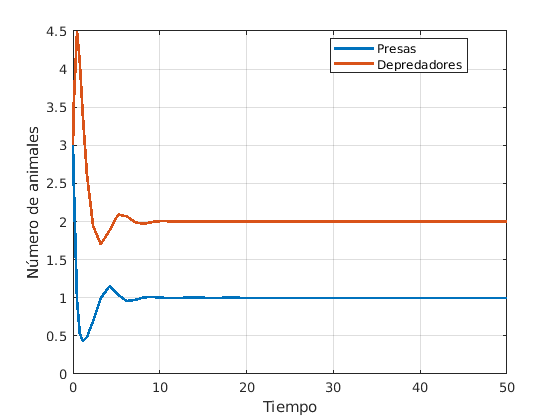

%graficar
figure
plot(t, P, "LineWidth", 2)
hold on
plot(t, D, "LineWidth", 2)

xlabel('Tiempo')
ylabel('Número de animales')
legend('Presas', 'Depredadores','Location',"best")
grid on

**4. **Identificar el comportamiento del modelo sin entrada

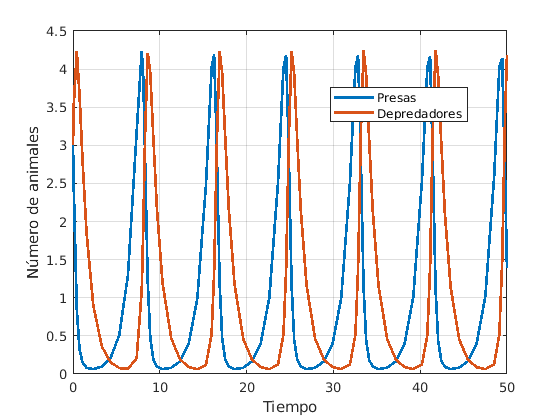

%entrada
u = 0;
options = simset('SrcWorkspace', 'current');
sim('Modelos/PresaDepredador_ejm2.slx', [], options);

%graficar
figure
plot(t, P, "LineWidth", 2)
hold on
plot(t, D, "LineWidth", 2)

xlabel('Tiempo')
ylabel('Número de animales')
legend('Presas', 'Depredadores','Location',"best")
grid on

## Utilizar otro tipos de entradas para la simulación

**1.** **Entrada de tipo seno**

En este caso, la entrada varía en el tiempo siguiendo ondas sinusoidales. Esta entrada está definida por tres parámetros:* u,* *Amplitud *y *Frequency.*

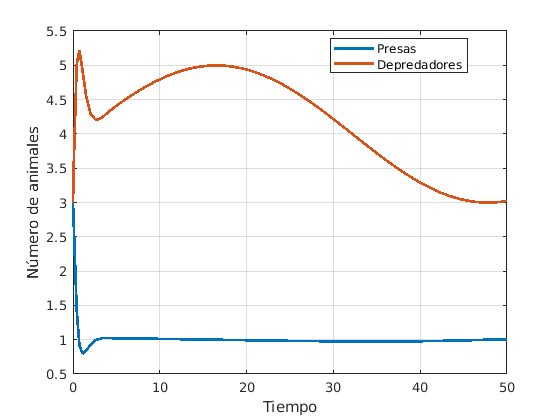

%Parámetros de la entrada de tipo seno
Amplitude = 1;
u = 3;
Frequency = 0.1;

options = simset('SrcWorkspace', 'current');
%Modelo con entrada tipo seno
sim('PresaDepredador_seno.slx', [], options);

%Tiempo de simulación
Time = 100;

%graficar
figure
plot(t, P, "LineWidth", 2)
hold on
plot(t, D, "LineWidth", 2)

xlabel('Tiempo')
ylabel('Número de animales')
legend('Presas', 'Depredadores','Location',"best")
grid on

**2.** **Entrada de tipo step**

En este caso, la entrada tiene un valor consante inicial (*u1*)*, *pero después de cierto tiempo (*StepTime*) la entrada cambia abruptamente a un valor de (*u2*).

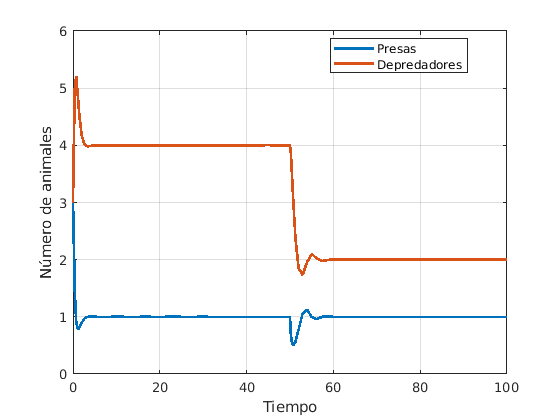

%Parámetros de la entrada de tipo step
StepTime = 50;
u1 = 3;
u2 = 1;

options = simset('SrcWorkspace', 'current');
%Modelo con entrada tipo seno
sim('PresaDepredador_step.slx', [], options);

%Tiempo de simulación
Time = 100;

%graficar
figure
plot(t, P, "LineWidth", 2)
hold on
plot(t, D, "LineWidth", 2)

xlabel('Tiempo')
ylabel('Número de animales')
legend('Presas', 'Depredadores','Location',"best")
grid on